## 1 a)

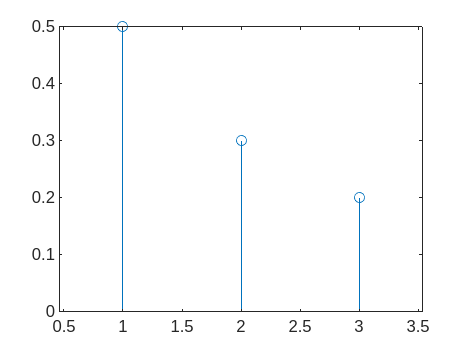

pXY = [0.3,0.2,0;0.1,0.15,0.05;0,0.1,0.1];
pX = sum(pXY, 2);
pY = sum(pXY, 1);
S = ones(size(pX));
Sx = cumsum(S);
stem(Sx, pX)

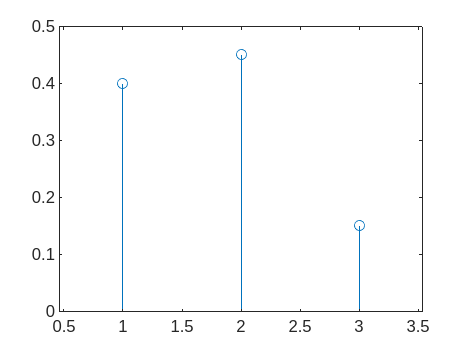

stem(Sx, pY)

## b)


Sx = 0:2;
Sy = Sx;
Ex = Sx * pX

Ex = 0.7000

Ey = pY * Sy'

Ey = 0.7500

Ex2 = Sx.^2 * pX;
Ey2 = pY * Sy'.^2; 
VarX = Ex2 - Ex^2

VarX = 0.6100

VarY = Ey2 - Ey^2

VarY = 0.4875

## c)

E_XY = sum(sum(Sx' * Sy .* pXY))

E_XY = 0.8500


Covar_XY = E_XY - Ex * Ey

Covar_XY = 0.3250


coef_corr = Covar_XY / (sqrt(VarX) * sqrt(VarY))

coef_corr = 0.5960

## 2 a)

pXY = [1/8,1/8,1/24;1/8,1/4,1/8;1/24,1/8,1/24];
pX = sum(pXY, 2);
pY = sum(pXY);

diff = pXY - (pX * pY)

diff =     0.0399   -0.0208   -0.0191
   -0.0208         0    0.0208
   -0.0191    0.0208   -0.0017


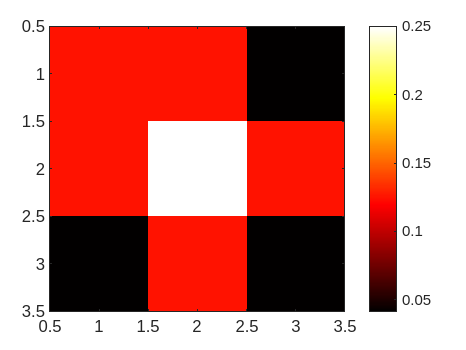


imagesc(pXY);
colormap(hot);
colorbar();

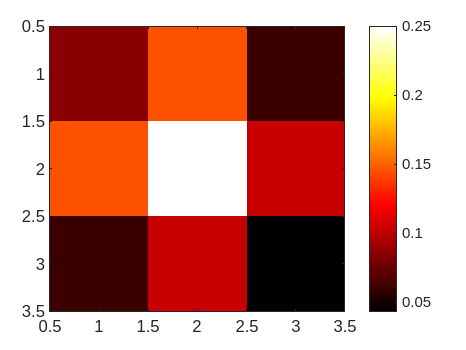


imagesc(pX*pY);
colormap(hot);
colorbar();

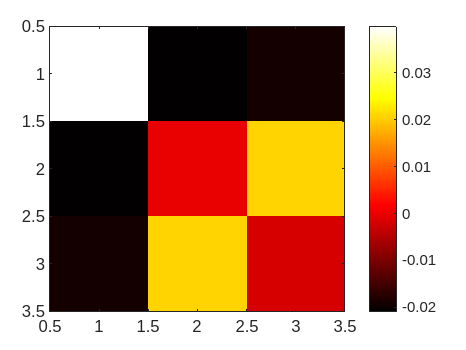


imagesc(diff);
colormap(hot);
colorbar();

## 3. a)

% N1 = MPEI
% N2 = POO

n_alunos = 120;
mediaN1 = 14;
mediaN2 = 1.2 * mediaN1;
var1 = (1/4) * mediaN1;
var2 = (1/4) * mediaN2;

aux1 = randn(1, n_alunos) * sqrt(var1) + mediaN1;
aux2 = randn(1, n_alunos) * sqrt(var2) + mediaN2;
N1 = round(aux1);
N2 = round(aux2);

S_N1 = min(N1):max(N1);
S_N2 = min(N2):max(N2);
p_N1N2 = zeros(length(S_N1), length(S_N2));

for n1 = 1:length(S_N1)
    for n2 = 1:length(S_N2)
        cfav = sum((N1 == S_N1(n1)) & (N2 == S_N2(n2)));
        p_N1N2(n1, n2) = cfav / n_alunos;
    end
end


## b)

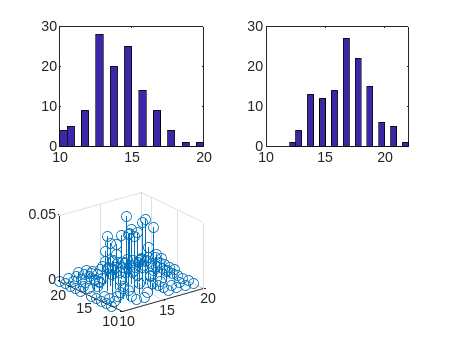

figure;

subplot(2, 2, 1);
hist(N1, 20);

subplot(2, 2, 2);
hist(N2, 20);


subplot(2, 2, 3);

stem3(S_N1', S_N2, p_N1N2);

## 4.

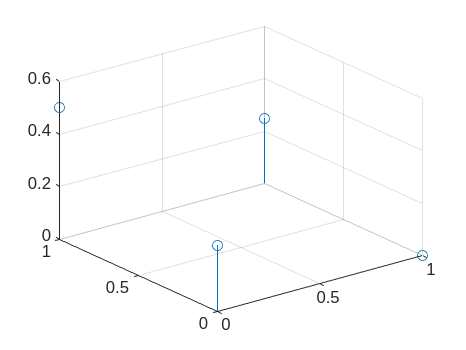

% X = Tempo { 0 chuva - 1 sol }
% Y = Previsão { 0 chuva - 1 sol }
pXY = [1/4, 0; 1/2, 1/4];
figure;
stem3(0:1, 0:1, pXY);;

pXY = [1/4,0;1/2,1/4];

